### Wireless project

%load the data
load roomPathData.mat

Create antenna arrays

fc=pathData.fc;
elem = design(patchMicrostrip, fc);
nantgNB = [4,4];
nantUE = [2,2];
lambda = physconst('Lightspeed') / fc;
dsep = 0.5*lambda;
arrgNB = phased.URA(nantgNB,dsep,'ArrayNormal','x');
arrUE  = phased.URA(nantUE,dsep,'ArrayNormal','x');

arrPlatformgNB = ArrayPlatform('elem', elem, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();
arrPlatformUE =  ArrayPlatform('elem', elem, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();

Orient the array

azUE = 105;
elUE = -10;
arrPlatformUE.alignAxes(azUE, elUE);

aoaAz=pathData.aoaAz(1000,: );
aoaEl=pathData.aoaEl(1000,: );
aodAz=pathData.aodAz(1000,: );
aodEl=pathData.aodEl(1000,: );
[svTx, elemGainTx] = arrPlatformgNB(aodAz', aodEl');
[svRx, elemGainRx] = arrPlatformUE(aoaAz', aoaEl');
pathgain=pathData.gain(1000,:);
gainElem = pathgain' + elemGainTx + elemGainRx;
gain=sum(db2mag(gainElem));
display(gain);%print the total element gain

gain = 2.6452e-04


azUE1 = -180:10:180;
elUE1 = -90:10:90;
gain=zeros(length(azUE1),length(elUE1));
for i =1:length(azUE1)
    for j=1:length(elUE1)
        arrPlatformUE.alignAxes(azUE1(i), elUE1(j));
        [svTx, elemGainTx] = arrPlatformgNB(aodAz', aodEl');
        [svRx, elemGainRx] = arrPlatformUE(aoaAz', aoaEl');
        gainElem = pathgain' + elemGainTx + elemGainRx;
        gain(i,j)=sum(db2mag(gainElem));
    end
end



In order the get the max throughput, I find the angle when the gain reaches maximum

[maxgain i]=max(gain(:));
[x,y]=find(gain==maxgain);
azUE2=azUE1(x);
elUE2=elUE1(y);

arrPlatformUE.alignAxes(azUE2, elUE2);
[svTx, elemGainTx] = arrPlatformgNB(aodAz', aodEl');
[svRx, elemGainRx] = arrPlatformUE(aoaAz', aoaEl');
gainElem = pathgain' + elemGainTx + elemGainRx;
gain2=sum(db2mag(gainElem));

dly=pathData.dly(1000,:);
SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB
carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

Enoise = -5; 
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz', 'aodAz', aodAz', 'aoaEl', aoaEl', 'aodEl', aodEl',  ...
    'gain', pathgain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);

frameNum = 0;
slotNum = 0;
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);


OFDM frequency domain channel

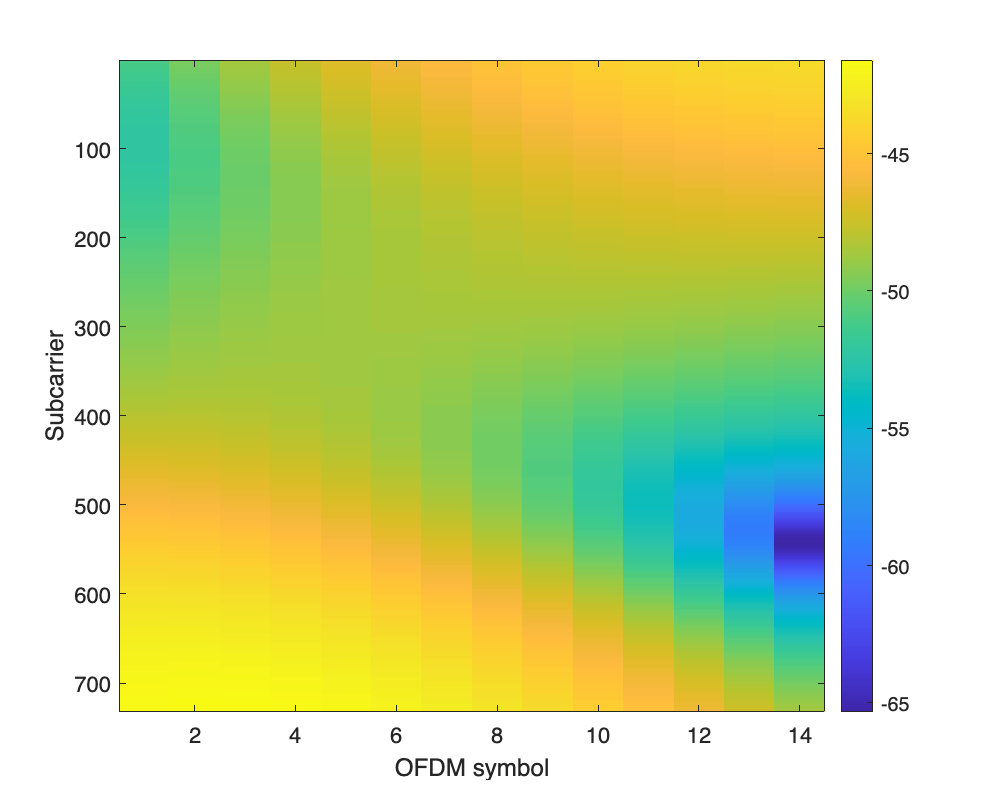

figure();
set(gcf,'Position', [0,0,500,400]);
chanGainSing = squeeze( abs(chanGrid(3,4,:,:)).^2 );
ChanSing = 10*log10(chanGainSing/noiseVar );
imagesc(ChanSing);
colorbar();
xlabel('OFDM symbol');
ylabel('Subcarrier');

maxsnr=max(10*log10(abs(chanGrid(:)).^2/noiseVar))

maxsnr = -38.0698

minsnr=min(10*log10(abs(chanGrid(:)).^2/noiseVar))

minsnr = -104.6736

DL PDSCH

dmrsConfig = nrPDSCHDMRSConfig(...
    'NumCDMGroupsWithoutData', 1, ...  % No unused DM-RS
    'DMRSAdditionalPosition', 1, ...   % Number additional DM-RS in time
    'DMRSConfigurationType', 2);       % 1=6 DM-RS per sym,  2=4 per sym

pdschConfig = nrPDSCHConfig();
pdschConfig.NSizeBWP = [];   % Empty implies that the value is equal to NSizeGrid
pdschConfig.NStartBWP = [];  % Empty implies that the value is equal to NStartGrid
pdschConfig.PRBSet = (0:NRB-1);   % Allocate the complete carrier
pdschConfig.SymbolAllocation = [0 14]; % Symbol allocation [S L]
pdschConfig.MappingType = 'A'; % PDSCH mapping type ('A' or 'B')
pdschConfig.EnablePTRS = true;
pdschConfig.PTRS =  nrPDSCHPTRSConfig();
pdschConfig.DMRS = dmrsConfig;



tx = NRgNBTxFD(carrierConfig, pdschConfig);
txgrid=tx.step();

rxgrid=zeros(size(chanGrid));

for i =1:length(rxgrid(:,1,1,1))
    for j=1:length(rxgrid(1,:,1,1))
        rxgrid(i,j,:,:)=squeeze(chanGrid(i,j,:,:)).*txgrid;
    end
end




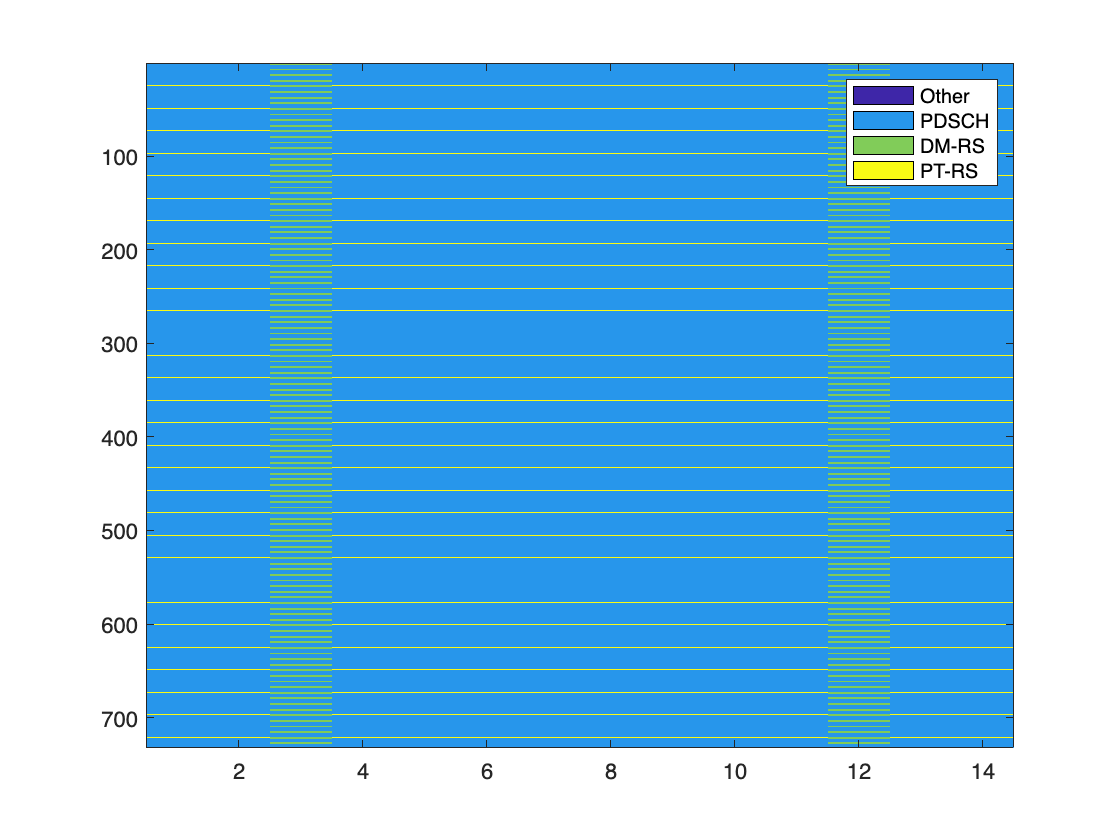

figure();
plotChan(tx.txGridChan, tx.chanNames);

rx = NRUERxFD(carrierConfig, pdschConfig);

Frequency domain equalization and LLR calculation 

% Get indices on where the PDSCH is allocated
pdschInd = nrPDSCHIndices(carrierConfig, pdschConfig);
pdschSymEq=zeros(length(rxgrid(:,1,1,1)),length(rxgrid(1,:,1,1)) ,length(pdschInd));
llr=zeros(length(rxgrid(:,1,1,1)),length(rxgrid(1,:,1,1)) ,length(pdschInd)*2);
for i =1:length(rxgrid(:,1,1,1))
    for j=1:length(rxgrid(1,:,1,1))           
        rxGrid=squeeze(rxgrid(i,j,:,:));
        pdschSym = rxGrid(pdschInd);
        chanGrid1=squeeze(chanGrid(i,j,:,:));
        pdschChan = chanGrid1(pdschInd);
        pdschSymEq(i,j,:) = conj(pdschChan).*pdschSym./(abs(pdschChan).^2 + noiseVar);
        llr(i,j,:) = qamdemod(squeeze(pdschSymEq(i,j,:)),4,'OutputType','approxllr', ...
        'UnitAveragePower',true,'NoiseVariance', noiseVar);
    end
end
            
         
%pdschSymEq = conj(pdschChan).*pdschSym./(abs(pdschChan).^2 + noiseVar);


Channel estimator

chanEstGrid=zeros(size(chanGrid));

for i =1:length(rxgrid(:,1,1,1))
    for j=1:length(rxgrid(1,:,1,1))           
        rx.chanEst(squeeze(rxgrid(i,j,:,:)));    
        chanEstGrid(i,j,:,:)=rx.chanEstGrid;
    end
end

